# 创建一个金刚石TB模型并拟合参数

## 创建模型

- 声明一个空的模型；初始化其轨道数

%addpath('..');
Diamond = HR(8)

Diamond =   HR - 属性:

        vectorL: [0 0 0]
          HnumL: [8×8 double]
          HcoeL: [8×8 sym]
          NRPTS: 1
        WAN_NUM: 8
       Line_000: 1
      Basis_num: []
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×0 sym]


- 修改POSCAR_Diamond格式

*generated by phonopy*

*   1.0*

*     0.0000000000000000    1.7868549235128819    1.7868549235128819*

*     1.7868549235128819    0.0000000000000000    1.7868549235128819*

*     1.7868549235128819    1.7868549235128819    0.0000000000000000*

*C*

*   8*

*Direct*

*  0.2500000000000000  0.2500000000000000  0.2500000000000000 C s ****I***

*  0.2500000000000000  0.2500000000000000  0.2500000000000000 C p x*

*  0.2500000000000000  0.2500000000000000  0.2500000000000000 C p y*

*  0.2500000000000000  0.2500000000000000  0.2500000000000000 C p z*

*  0.0000000000000000  0.0000000000000000  0.0000000000000000 C s ****I***

*  0.0000000000000000  0.0000000000000000  0.0000000000000000 C p x*

*  0.0000000000000000  0.0000000000000000  0.0000000000000000 C p y*

*  0.0000000000000000  0.0000000000000000  0.0000000000000000 C p z*

- 导入POSCAR

Diamond = Diamond <'POSCAR_Diamond'

Diamond =   HR - 属性:

        vectorL: [0 0 0]
          HnumL: [8×8 double]
          HcoeL: [8×8 sym]
          NRPTS: 1
        WAN_NUM: 8
       Line_000: 1
      Basis_num: 8
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×0 sym]


- 进行 nn_sk 搜索

- 这里 search_range 取 【2 2 2】因为是小开角元胞

- Accuracy 取小数点3位，maxR值取 2.8 埃

search_range = [2 2 2];
Accuracy = 3;
r_max_search = 2.8;
Diamond = Diamond.nn(search_range,Accuracy ,r_max_search);

Generating 8/8 th orb nn information ...
Giving nn_level for 128/128 th hopping  ...


- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = Diamond.nn_information();

- 这里我们取最近邻hopping

- 我们关心 s轨道与p轨道的劈裂

Diamond = Diamond.H_TBSK_gen('level_cut',1,'per_dir',[1 1 1],'onsite',true); 

Generating Symbolic Hopping term ...< ok >
Setting NRPT 7/7 ...


- 查看一下体系的未知量（symbolic）

Diamond.symvar_list

$$ans = \left(\begin{array}{cccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

- 导入 KPOINTS信息 高对称点 高对称路径

- 这里额外配置高对称点

Diamond = Diamond<'KPOINTS_Diamond';
[klist_l,kpoints_l,kpoints_name] = Diamond.kpath_information();

## 利用MATLAB(2020)控件调整参数

- 创建滑块

E__6_0 = 0;
E__6_1 = 0;
VppP_1 = 4;
VppS_1 = -11;
VspS_1 = 0;
VssS_1 = 0;
Fermi  = 0;

- 给TB中的符号化变量赋值

Diamond_n = Diamond.Subsall();

- 生成能带

EIGENCAR = Diamond_n.EIGENCAR_gen()-Fermi;

BAND calculating 360/360 ...


- 画出能带

bandplot(EIGENCAR,[-10,10],'title',"Diamond-TB-VppP_1="+string(VppP_1),'Color','b','POSCAR','POSCAR_Diamond','KPOINTS','KPOINTS_Diamond');

## 利用MATLAB(2020)控件调整参数 - DFT

- 导入DFT数据

Efermi =  9.85855597;
EIGENCAR_DFT = EIGENVAL_read('vasp','EIGENVAL_Diamond',Efermi); 

- 创建滑块

E__6_0 = 0;
E__6_1 = 0;
VppP_1 = 14;
VppS_1 = -6;
VspS_1 = -7;
VssS_1 = 5;
Fermi  = 0;

- 给TB中的符号化变量赋值

Diamond_n = Diamond.Subsall();

- 生成能带

EIGENCAR = Diamond_n.EIGENCAR_gen()-Fermi;

BAND calculating 360/360 ...


- 画出能带

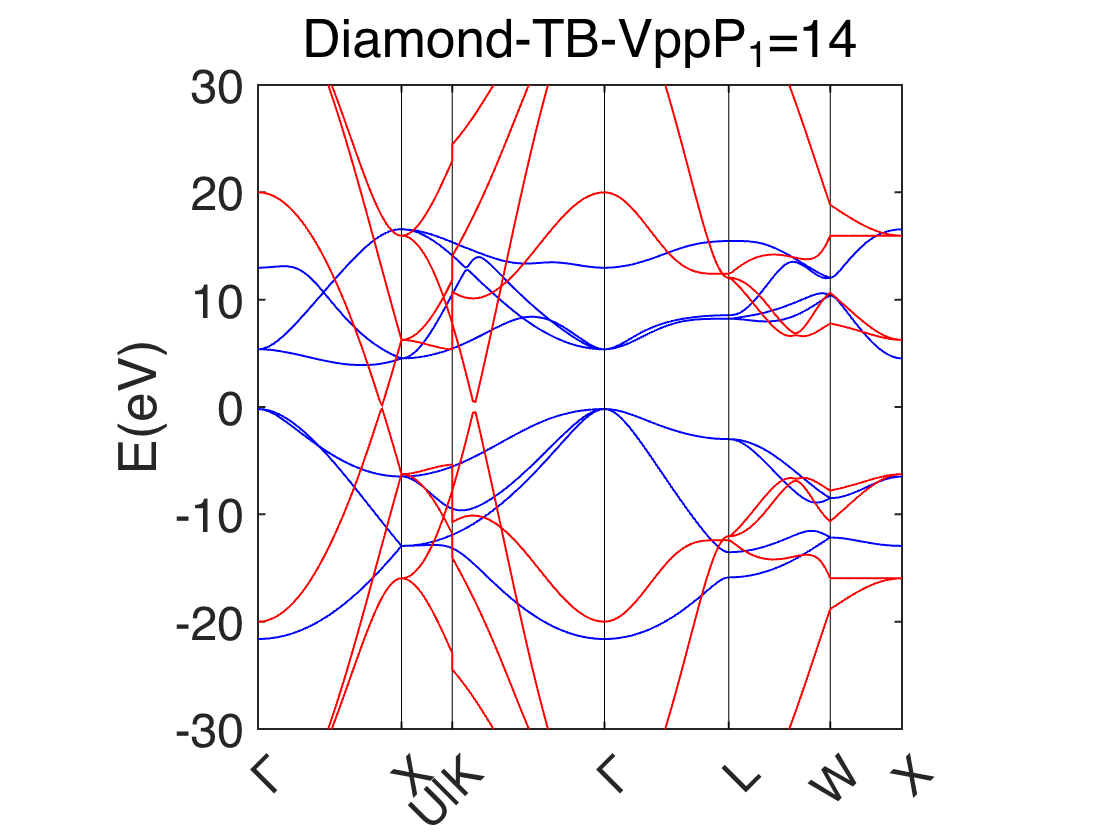

[fig,ax]= bandplot(EIGENCAR_DFT,[-30,30],'title',"Diamond-TB-VppP_1="+string(VppP_1),'Color','b','POSCAR','POSCAR_Diamond','KPOINTS','KPOINTS_Diamond');
[fig,ax]= bandplot(EIGENCAR ,[-30,30],'title',"Diamond-TB-VppP_1="+string(VppP_1),'fig',fig,'ax',ax,...
    'POSCAR','POSCAR_Diamond','Color','r','KPOINTS','KPOINTS_Diamond');

## 利用NM办法多参数拟合DFT (初值依赖)

### NM

Efermi =  9.85855597;
EIGENCAR_DFT = EIGENVAL_read('vasp','EIGENVAL_Diamond',Efermi);
Diamond = Diamond.subs(sym('E__6_0'),0);

#### 拟合参数设置

设定拟合范围：

options_extra.NBAND_range_DFT = [1:4];
options_extra.NBAND_range = [1:4];
options_extra.klist_range = ':';
options_extra.E_range = [];

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

%SKTB_single = subs(SKTB);
Loss_func_TB = @(para) vasplib.loss_func(para, ...
    'FITobj','Diamond',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)     

Loss_func_TB = 包含以下值的 function_handle :
    @(para)vasplib.loss_func(para,'FITobj','Diamond','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


#### 初值给定

%SKTB = SKTB.subs([sym('E__6_1') sym('VppP_1')],[0,2.71353]);
% SKTB.symvar_list
x0 = [ E__6_1, VppP_1, VppS_1, VspS_1, VssS_1];

#### 进行拟合

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          13.3084         
     1            6          13.3051         initial simplex
     2            8          11.7316         expand
     3            9          11.7316         reflect
     4           10          11.7316         reflect
     5           11          11.7316         reflect
     6           13          10.6409         expand
     7           15          9.14358         expand
     8           16          9.14358         reflect
     9           18          7.62548         expand
    10           19          7.62548         reflect
    11           21          4.62358         expand
    12           22          4.62358         reflect
    13           24           3.3651         expand
    14           26          3.24149         reflect
    15           27          3.24149         reflect
    16           29          3.24149         contract outside
    17           31          3.24149  

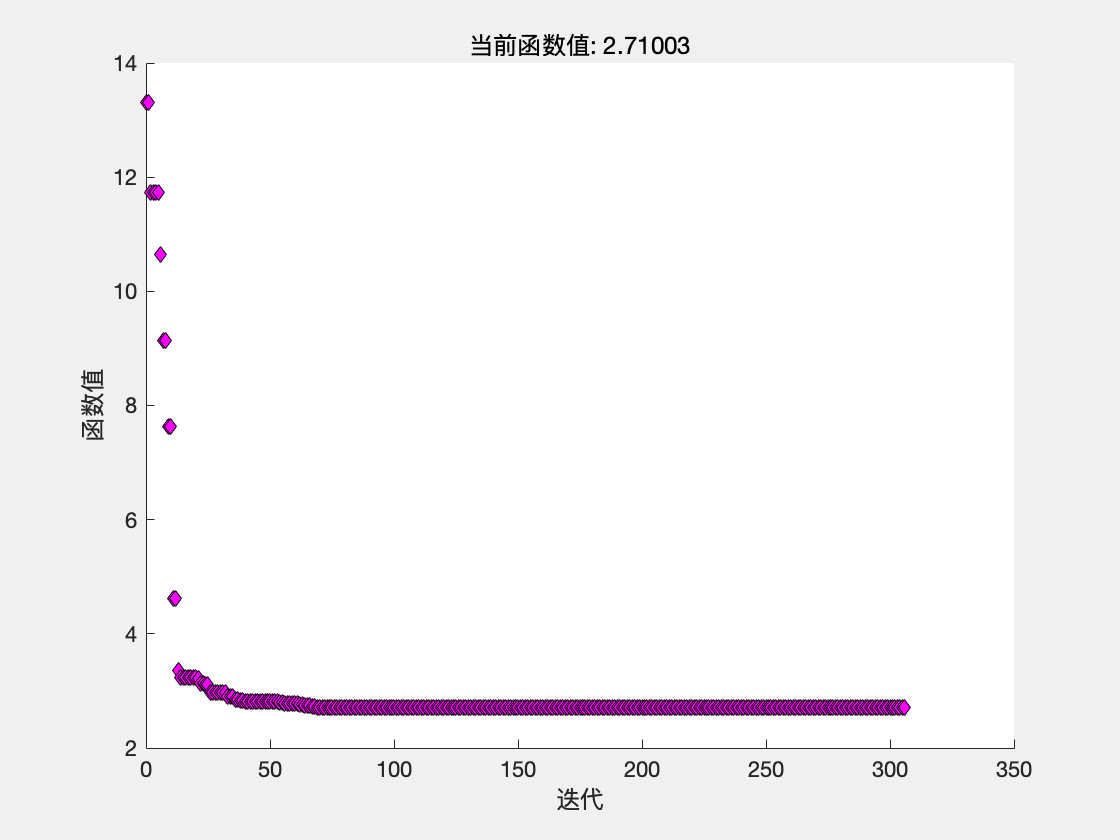

 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件，
F(X) 满足使用 1.000000e-04 的 OPTIONS.TolFun 的收敛条件



options = optimset('PlotFcns',@optimplotfval,'Display','iter');
x = fminsearch(Loss_func_TB,x0,options);result = mat2cell(x,1,ones(1,length(x)));

E__6_1 = x(1)

E__6_1 = 9.0193e-04

VppP_1 = x(2)

VppP_1 = 2.3198

VppS_1 = x(3)

VppS_1 = -8.7092

VspS_1 = x(4)

VspS_1 = -7.2200

VssS_1 = x(5)

VssS_1 = 5.5173

- 给TB中的符号化变量赋值

Diamond_n = Diamond.Subsall();

- 生成能带

EIGENCAR = Diamond_n.EIGENCAR_gen()-Fermi;

BAND calculating 360/360 ...


- 画出能带

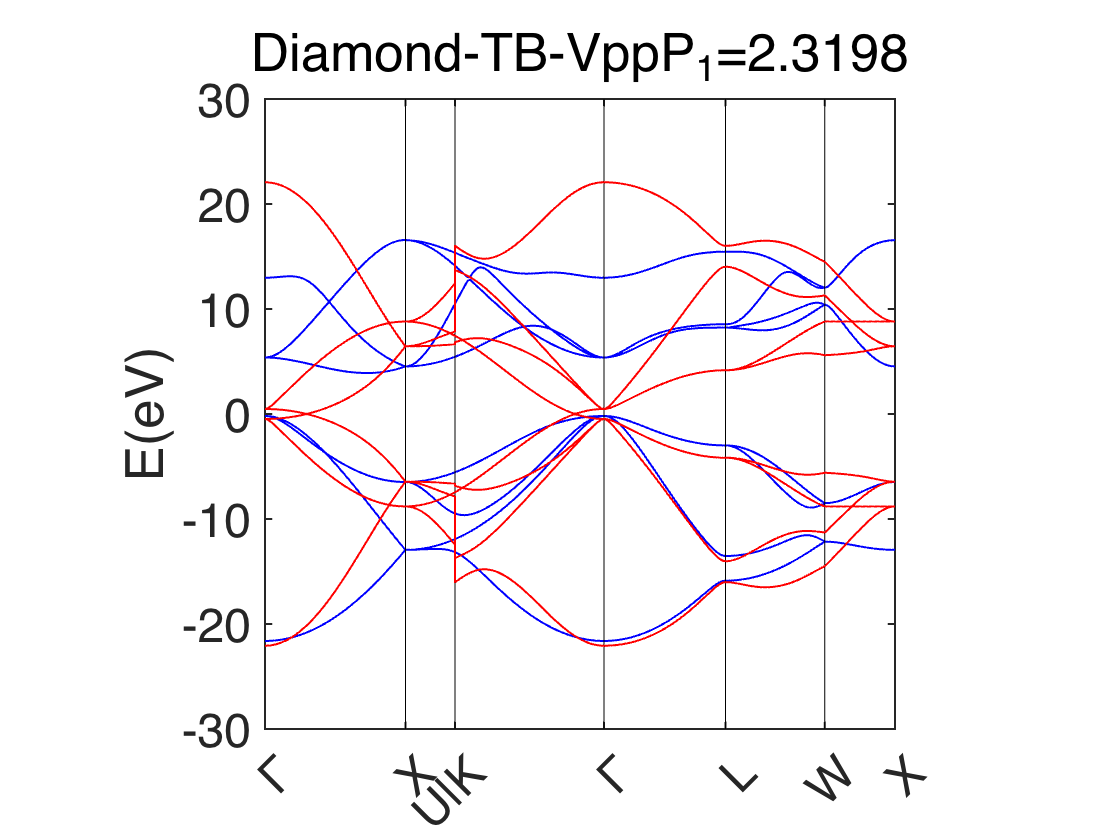

fontname = "Helvetica";
[fig,ax]= bandplot(EIGENCAR_DFT,[-30,30],'title',"Diamond-TB-VppP_1="+string(VppP_1),'Color','b','POSCAR','POSCAR_Diamond','KPOINTS','KPOINTS_Diamond');
[fig,ax]= bandplot(EIGENCAR ,[-30,30],'title',"Diamond-TB-VppP_1="+string(VppP_1),'fig',fig,'ax',ax,...
    'POSCAR','POSCAR_Diamond','Color','r','KPOINTS','KPOINTS_Diamond');